Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Pill-box cavity with beam pipe (Section 6.4.2)

Volker Ziemann, 211124, CC-BY-SA-4.0

**Important:** this example requires the PDE toolbox!

In this example we calculate the eigenfrequencies of a pill-box cavity with a beam pipe connected to its center. This will perturb the eigenmodes and eigenfrequencies of a pure cavity. We therefore use the PDE toolbox to find the TM eigenmodes and note that the system is still rotationally symmetric such that we can use a 2D model to find the rotationally symmetric modes.

We first define the beam pipe radius `rr`, the cavity radius `R`, and the the cavity length `L` to specify the cavity dimensions.

clear; 
rr=0.01  % Slider for the beam pipe radius

rr = 0.0100

R=0.23  % Slider for the cavity radius

R = 0.2300

L=0.3;   % Cavity length

Now we use these parameters to define the cavity and the beam pipe as three polygons `Cav, Pl,` and `Pr,` assemble them in `gd`, define names `ns` and specify the relation `sf` among the regions, before we construct the geometry `g` and create the model for one parameter `u = `$E_z$. Then we add the geometry `g` to it and inspect the model to note the `EdgeLabels` and the `SubDomainLabels.`

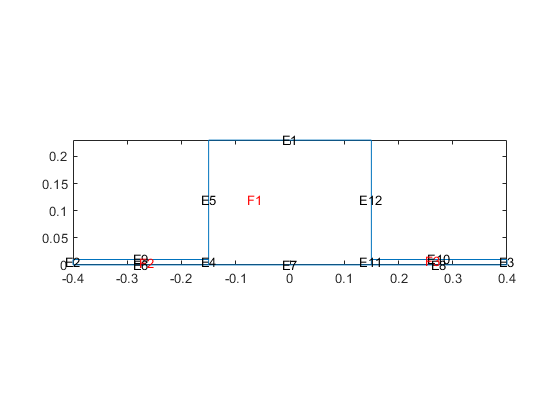

Cav=[2;4; -L/2;L/2;L/2;-L/2;  0.0;0.0;R;R];       % cavity
Pl=[2;4; -0.4;-L/2;-L/2;-0.4;  0.0;0.0;rr;rr];    % pipe left
Pr=[2;4; L/2;0.4;0.4;L/2;  0.0;0.0;rr;rr];        % pipe right
gd=[Cav,Pl,Pr];                % assemble geometry
ns=char('Cavity','Pl','Pr')';  % names of the regions                 
sf='Cavity+Pl+Pr';             % geometry relations
g=decsg(gd,sf,ns); 
model=createpde(1);
geometryFromEdges(model,g);
pdegplot(model,'EdgeLabels','on','SubDomainLabels','on'); axis tight

Since the longitudinal electric field `u = `$E_z$ must vanish on the boundaries where it is parallel to the boundaries E1, E9, E10 and on the exit from the beam pipe E2 and E3, we select Dirichlet boundary conditions. On the verical walls E5 and E12 the electric field is given by the derivative of the longitudinal field $E_z$, which implies the use of von-Neumann boundary conditions. Moreover, we also use von-Neumann conditions on the symmetry axis E6, E7, and E8. 

applyBoundaryCondition(model,'Edge',[1,2,3,9,10],'u',0);       % Dirichlet
applyBoundaryCondition(model,'Edge',[6,7,8,5,12],'q',0,'g',0); % Neumann

The rotational symmetry requires to use the Laplace operator in cylindrical coordinates, which has to be brought into Matlab's generic form to specify a  partial differential equation in divergence form, which is discussed further in Section 6.4.2. In the code this is accomplished by using functions `cfun()` and `dfun()` when specifying the material properties.

cfun=@(location,state)-location.y;
dfun=@(location,state)-location.y;
specifyCoefficients(model,'m',0,'d',dfun,'c',cfun,'a',0,'f',0);

At this point we can mesh the geometry... 

generateMesh(model,'Hmax',0.01);
%figure; pdemesh(model); axis tight

...and solve the eigenvalue system with `solvepdeeig()`, which returns the structure `result` that contains the `Eigenvalues` and the `Eigenvectors` as members.

result=solvepdeeig(model,[1,800]); 

              Basis= 10,  Time=   0.09,  New conv eig=  0
              Basis= 12,  Time=   0.11,  New conv eig=  0
              Basis= 14,  Time=   0.12,  New conv eig=  2
              Basis= 16,  Time=   0.12,  New conv eig=  3
              Basis= 18,  Time=   0.13,  New conv eig=  3
              Basis= 20,  Time=   0.13,  New conv eig=  4
              Basis= 22,  Time=   0.14,  New conv eig=  5
End of sweep: Basis= 22,  Time=   0.14,  New conv eig=  5
              Basis= 15,  Time=   0.17,  New conv eig=  0
End of sweep: Basis= 15,  Time=   0.17,  New conv eig=  0


k2=result.Eigenvalues; 
Ez=result.Eigenvectors;

From the eigenvectors, which are $k^2=\omega^2/c^2$ we derive the frequencies of the eigenmodes in GHz.

freq_GHz=sqrt(k2')*3e8/(2*pi*1e9)   

freq_GHz =     0.5138    0.7271    1.1253    1.1655    1.2768


Since we are interested in the accelerating mode around 500 MHz, we choose to inspect the lowest-frequency mode=1 and first use `meshToPet()` to obtain information about the points `p`, edges `e`, and triagnles `t` of the mesh, such that we can use `pdeInterpolant()` to prepare a interpolant structure `F` that allows us to find the field at  points that are not on grid points. We use it to find the field `Ez0` in the center of the cavity and then use that to normalize u = $E_z$ to its maximum value at the center and display it with equipotential lines superimposed. We observe that the equipotential lines at large radius are almost parallel to the z-axis, which is what we would also observe in the analytical solution from Section 5.1. At smaller radii, however, we find the equipotential lines successively more distorted at smaller radii. 

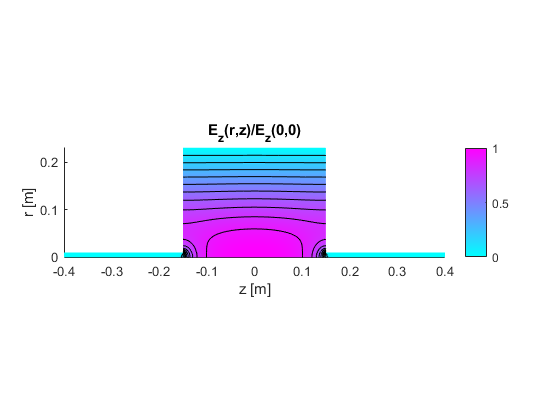

mode=1;    % mode to view and analyze
[p,e,t]=meshToPet(model.Mesh);
F=pdeInterpolant(p,t,Ez(:,mode)); 
Ez0=evaluate(F,0,0);
figure; pdeplot(model,'xydata',Ez(:,mode)/Ez0,'contour','on'); 
xlabel('z [m]'); ylabel('r [m]'); axis tight
title('E_z(r,z)/E_z(0,0)')

In the next figure we use the interpolant `F` to evaluate $E_z$ at z=0 along the radial direction and compare this to the analytical result from Equation 5.21 $E_z\propto J_0(2.405 r/R_{cav})$, where 2.405 is the first zero of $J_0(x)$. The figure shows good agreement between the two curves, because the center of the cavity is far away from the beam pipe entry points.

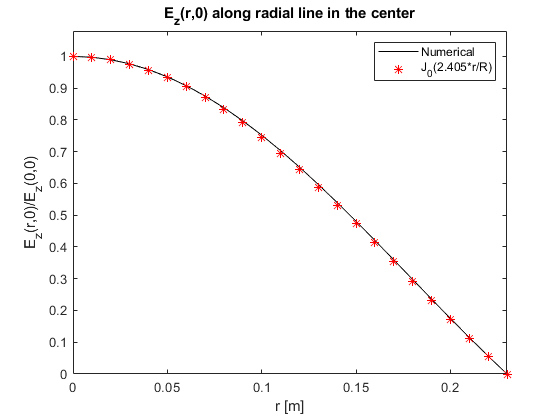

y=0:0.01:R; x=0*L*ones(1,length(y));       % define line
Ez=evaluate(F,x,y)/Ez0;                    % Ez on that line
Ez_analytic=besselj(0,2.405*y/R);          % eq. 5.21
figure; plot(y,Ez,'k',y,Ez_analytic,'r*'); 
xlabel('r [m]'); ylabel('E_z(r,0)/E_z(0,0)'); xlim([0,R]); ylim([0,1.08]);
title('E_z(r,0) along radial line in the center')
legend('Numerical','J_0(2.405*r/R)')

Finally, we calculate the accelerating field $E_z$ that the beam 'sees', which is along the center line at r=0. We also calculate $E_z$ at half the cavity radius $R/2$. For comparison we note that the analytic solution from Equation 5.21 for $p=k_zL=0$ is constant along the z-axis. Here, on the other hand, we see a significant distortion. Especially at $r=0$ the field decreases towards the cavity ends at $z=\pm L/2$ and even 'leaks' somewhat into the beam pipe. The fields $E_z$ at $R/2$, shown as the red line, is not constant either, but much less distorted.

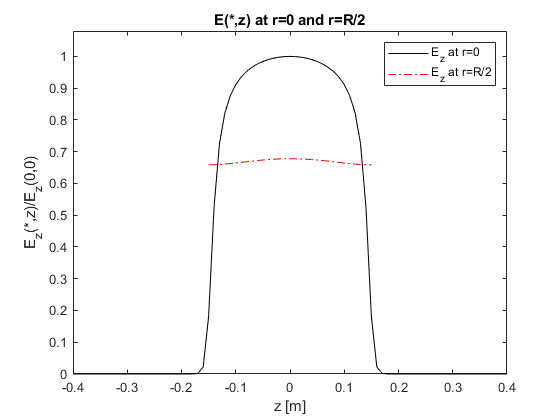

x=-0.4:0.01:0.4; y=0*ones(1,length(x));    % line in center of cavity
Ez1=evaluate(F,x,y)/Ez0;                   % Ez on center line
y=0.5*R*ones(1,length(x));                 % line at R/2
Ez2=evaluate(F,x,y)/Ez0;                   % Ez at R/2
figure; plot(x,Ez1,'k',x,Ez2,'r-.'); 
xlabel('z [m]'); ylabel('E_z(*,z)/E_z(0,0)'); ylim([0,1.08]);
title('E(*,z) at r=0 and r=R/2')
legend('E_z at r=0','E_z at r=R/2')

And now it's time to play around with this model. First you may increase the beam pipe radius and second, you might want to change the radius $R$ of the cavity to tune it to 500 MHz. In the present configuration it is a bit off-frequency.